Lista 03 - Modelagem e Identificação de Sistemas - SEL0359 - Controle Digital

Aluno: Vitor Augusto Tibério - 14658834 - Eng. Elétrica - EESC/USP

Prof. Dr. Marcos Rogério Fernandes 

## Atividade 01 - Diferentes Métodos de Discretização

Questão (1)

close all 
clear all 
clc 
% Definindo a função de transferência contínua: 
a = pi;
s = tf('s');
G = s / (s+a)^2; 
syms s a 
G_sym = s / (s+a)^2;
pretty(G_sym)

    s
--------
       2
(a + s)



% Obtendo as funções de transferência discreta
Ts = 0.1;
Gd_zoh = c2d(G, Ts, 'zoh');
Gd_impulse = c2d(G, Ts, 'impulse')


Gd_impulse =
 
   0.1 z^2 - 0.09599 z
  ----------------------
  z^2 - 1.461 z + 0.5335
 
Sample time: 0.1 seconds
Discrete-time transfer function.


Gd_matched = c2d(G, Ts, 'matched')


Gd_matched =
 
   0.07364 z - 0.07364
  ----------------------
  z^2 - 1.461 z + 0.5335
 
Sample time: 0.1 seconds
Discrete-time transfer function.


Gd_tustin = c2d(G, Ts, 'tustin')


Gd_tustin =
 
  0.03735 z^2 - 0.03735
  ----------------------
  z^2 - 1.457 z + 0.5307
 
Sample time: 0.1 seconds
Discrete-time transfer function.


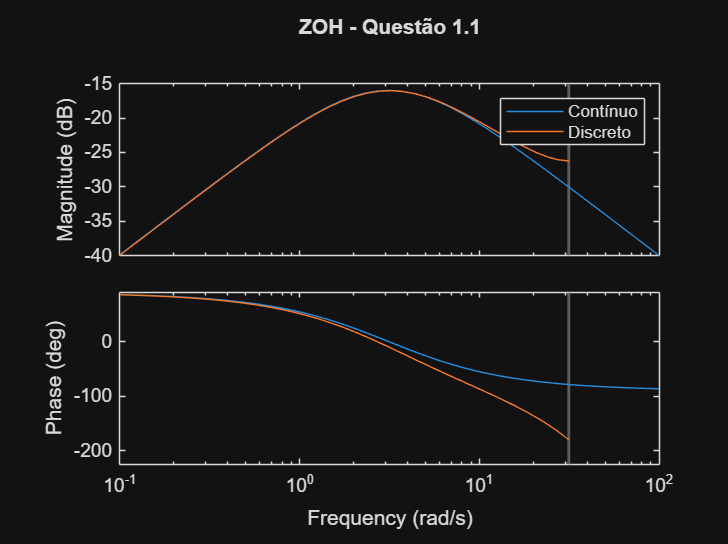

% Traçando a resposta em frequência de cada função
figure 
bode(G, Gd_zoh)
title('ZOH - Questão 1.1')
legend('Contínuo', 'Discreto')

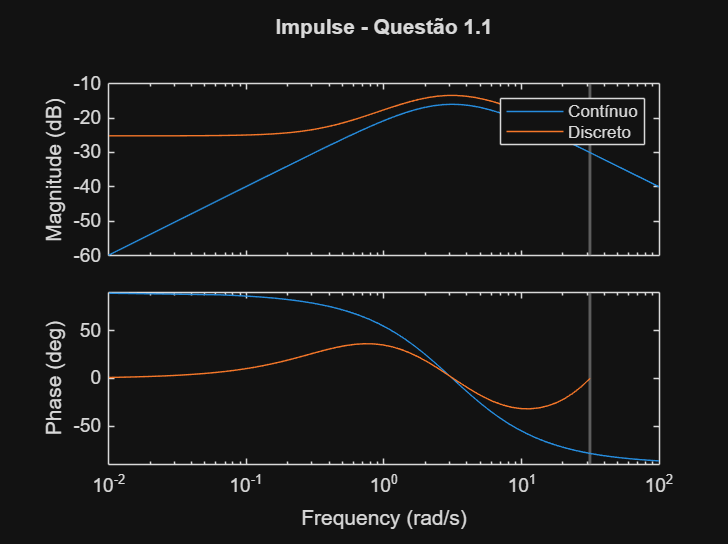

figure 
bode(G, Gd_impulse)
title('Impulse - Questão 1.1')
legend('Contínuo', 'Discreto')

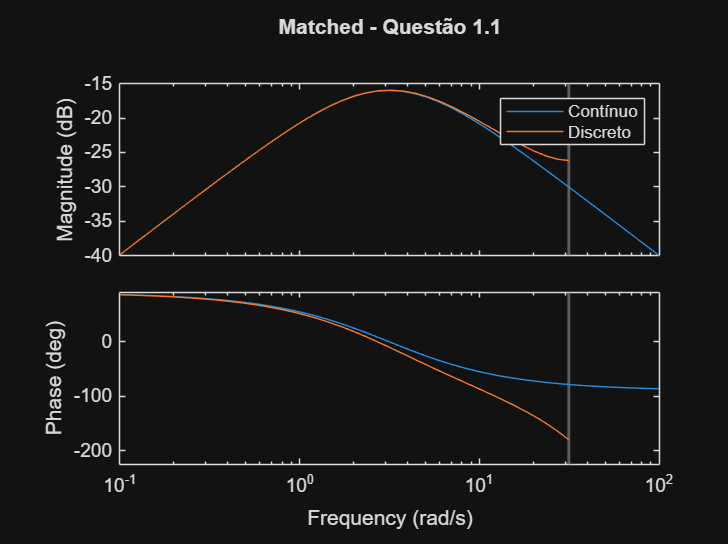

figure 
bode(G, Gd_matched)
title('Matched - Questão 1.1')
legend('Contínuo', 'Discreto')

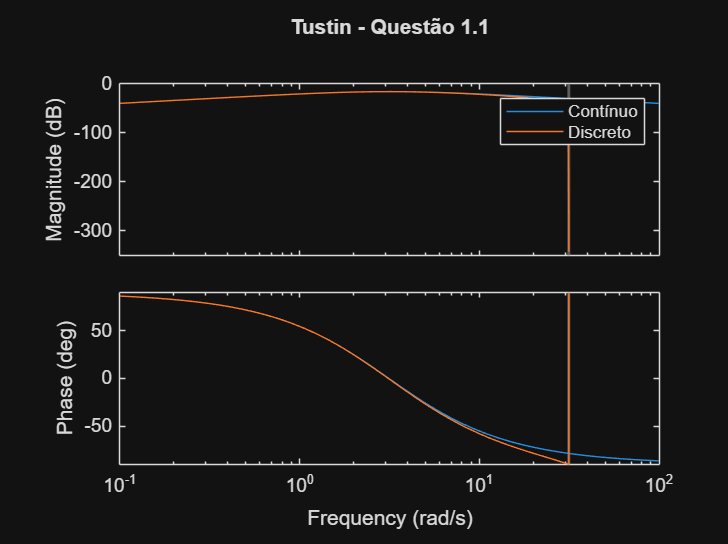

figure
bode(G, Gd_tustin)
title('Tustin - Questão 1.1')
legend('Contínuo', 'Discreto')

Questão (2)

clear all 
close all 
clc 
% Definindo a função de transferência contínua: 
num = [1 1 1];
den = [1 2 3 2];
G = tf(num, den);
%Definindo a função de transferência contínua simbólica (para simples
%conferência):
syms s
num_sym = poly2sym(num, s);
den_sym = poly2sym(den, s);
G_sym = num_sym / den_sym;
pretty(G_sym)

      2
     s  + s + 1
-------------------
 3      2
s  + 2 s  + 3 s + 2



% Obtendo as funções de transferência discretas:
Ts = 0.1;
Gd_zoh = c2d(G, Ts, 'zoh');
Gd_impulse = c2d(G, Ts, 'impulse')


Gd_impulse =
 
  0.1 z^3 - 0.1891 z^2 + 0.09005 z - 9.645e-22
  --------------------------------------------
       z^3 - 2.791 z^2 + 2.611 z - 0.8187
 
Sample time: 0.1 seconds
Discrete-time transfer function.


Gd_matched = c2d(G, Ts, 'matched')


Gd_matched =
 
   0.09508 z^2 - 0.1802 z + 0.08603
  ----------------------------------
  z^3 - 2.791 z^2 + 2.611 z - 0.8187
 
Sample time: 0.1 seconds
Discrete-time transfer function.


Gd_tustin = c2d(G, Ts, 'tustin')


Gd_tustin =
 
  0.04751 z^3 - 0.04254 z^2 - 0.04705 z + 0.04299
  -----------------------------------------------
         z^3 - 2.791 z^2 + 2.612 z - 0.819
 
Sample time: 0.1 seconds
Discrete-time transfer function.


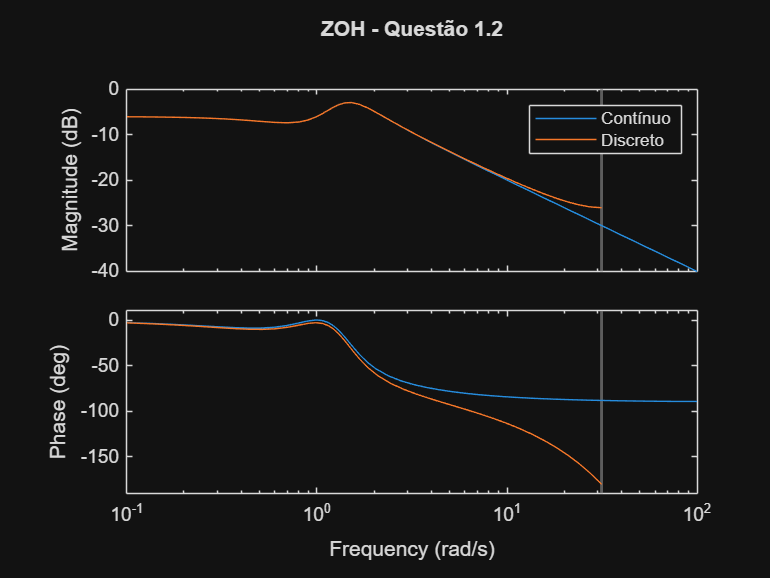

% Traçando a resposta em frequência de cada função
figure 
bode(G, Gd_zoh)
title('ZOH - Questão 1.2')
legend('Contínuo', 'Discreto')

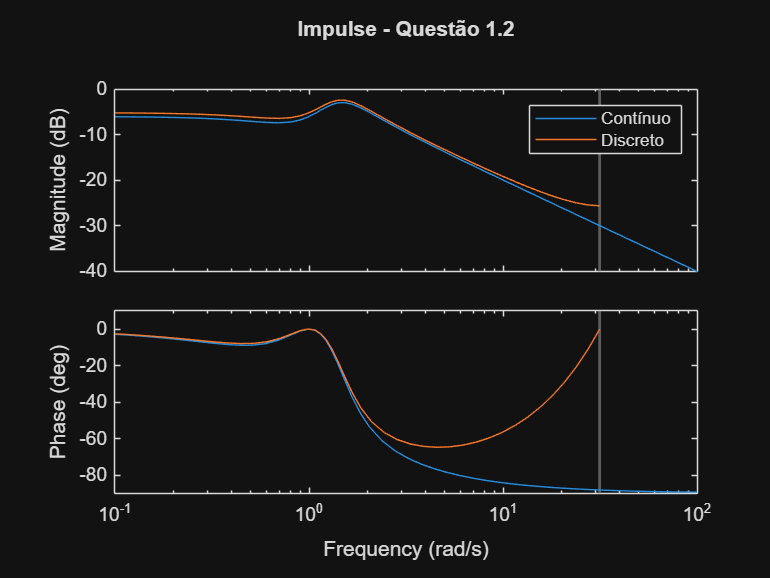

figure 
bode(G, Gd_impulse)
title('Impulse - Questão 1.2')
legend('Contínuo', 'Discreto')

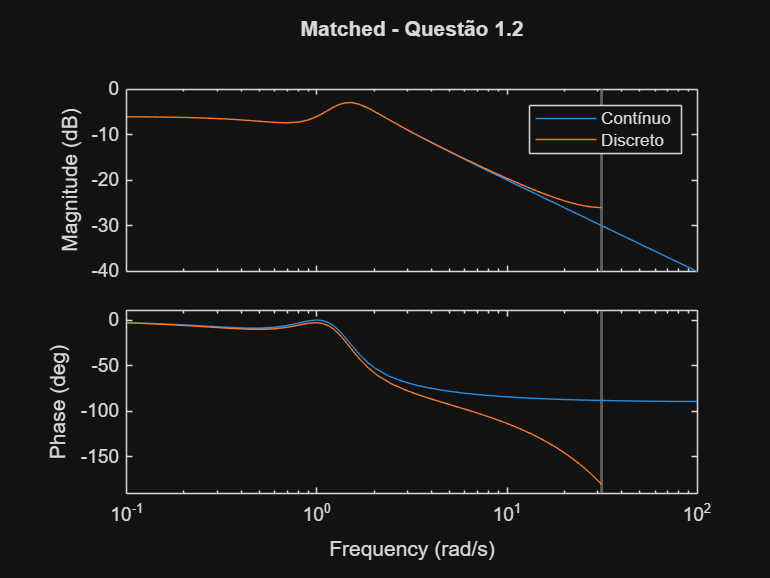

figure 
bode(G, Gd_matched)
title('Matched - Questão 1.2')
legend('Contínuo', 'Discreto')

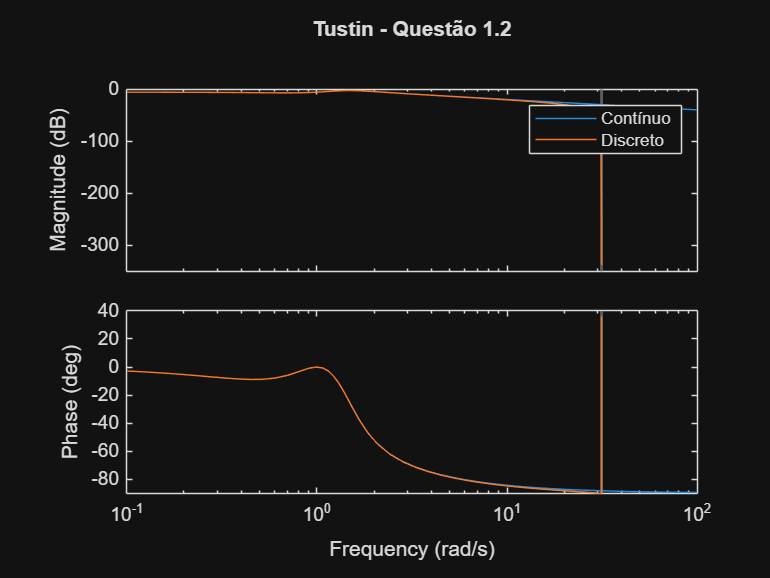

figure
bode(G, Gd_tustin)
title('Tustin - Questão 1.2')
legend('Contínuo', 'Discreto')

Questão (3)

clear all 
close all 
clc 
% Definindo a função de transferência contínua: 
num = 1;
den = [1 0 3 2 1];
G = tf(num, den);
%Definindo a função de transferência contínua simbólica (para simples
%conferência):
syms s
num_sym = poly2sym(num, s);
den_sym = poly2sym(den, s);
G_sym = num_sym / den_sym;
pretty(G_sym)

         1
-------------------
 4      2
s  + 3 s  + 2 s + 1



% Obtendo as funções de transferência discretas:
Ts = 0.1;
Gd_zoh = c2d(G, Ts, 'zoh');
Gd_impulse = c2d(G, Ts, 'impulse')


Gd_impulse =
 
  1.664e-05 z^3 + 6.647e-05 z^2 + 1.664e-05 z + 2.586e-18
  -------------------------------------------------------
         z^4 - 3.969 z^3 + 5.94 z^2 - 3.971 z + 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.


Gd_matched = c2d(G, Ts, 'matched')


Gd_matched =
 
  1.247e-05 z^3 + 3.741e-05 z^2 + 3.741e-05 z + 1.247e-05
  -------------------------------------------------------
         z^4 - 3.969 z^3 + 5.94 z^2 - 3.971 z + 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.


Gd_tustin = c2d(G, Ts, 'tustin')


Gd_tustin =
 
  6.202e-06 z^4 + 2.481e-05 z^3 + 3.721e-05 z^2 + 2.481e-05 z + 6.202e-06
  -----------------------------------------------------------------------
               z^4 - 3.969 z^3 + 5.939 z^2 - 3.97 z + 0.9995
 
Sample time: 0.1 seconds
Discrete-time transfer function.


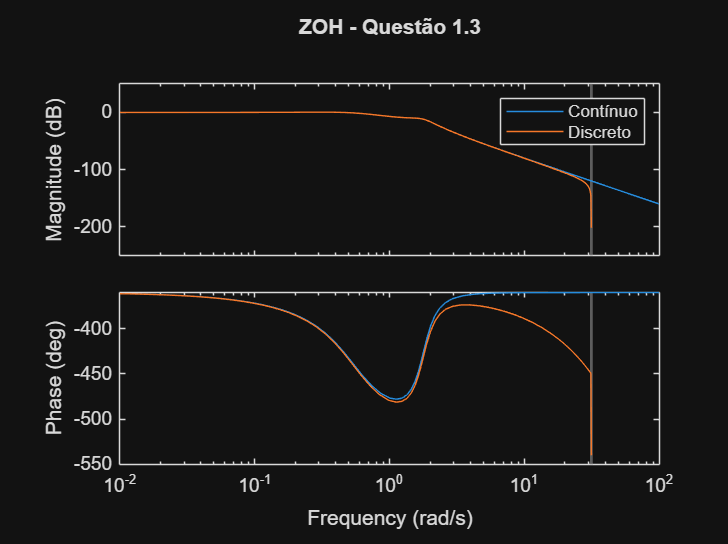

% Traçando a resposta em frequência de cada função
figure 
bode(G, Gd_zoh)
title('ZOH - Questão 1.3')
legend('Contínuo', 'Discreto')

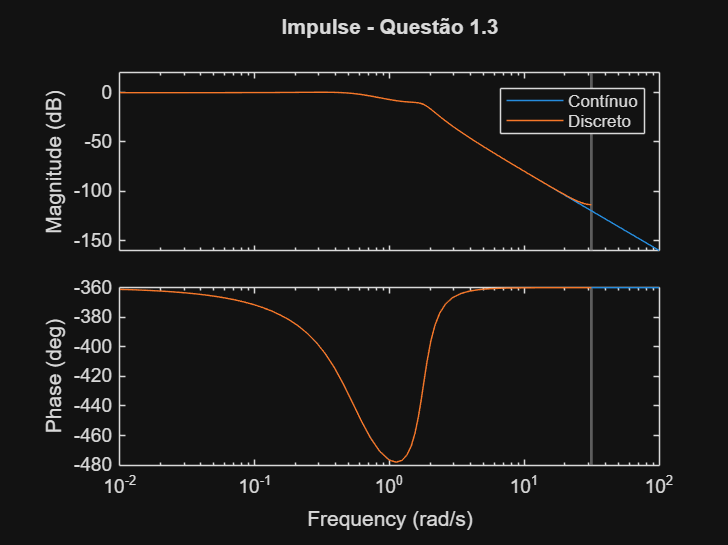

figure 
bode(G, Gd_impulse)
title('Impulse - Questão 1.3')
legend('Contínuo', 'Discreto')

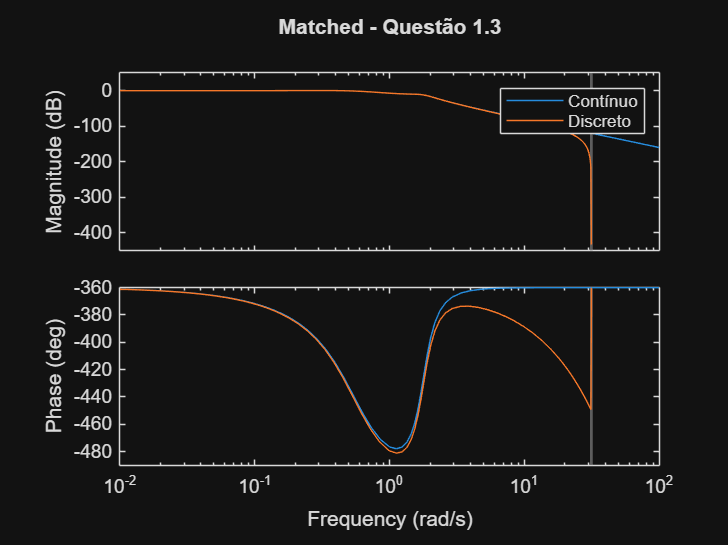

figure 
bode(G, Gd_matched)
title('Matched - Questão 1.3')
legend('Contínuo', 'Discreto')

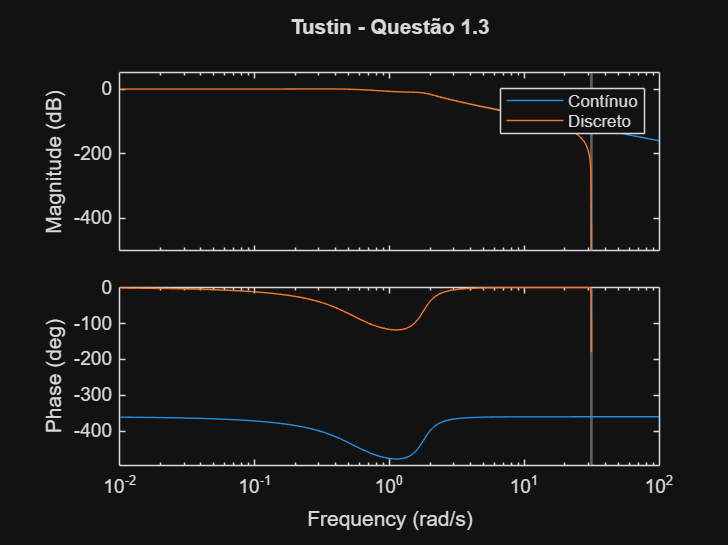

figure
bode(G, Gd_tustin)
title('Tustin - Questão 1.3')
legend('Contínuo', 'Discreto')

**Resposta:** Em relação à resposta em frequência para os diferentes métodos de discretização que foram utilizados, nota-se que o método de tustin é o único método que tem um "casamento" de fase e magnitude em relação ao sinal contínuo. Todos os outros métodos possuem variações (ou de fase, ou de magnitude ou ambos) do sinal discreto em relação ao contínuo. 

## Atividade 02 - Cálculo Simbólico

Questão (1)

clear all 
close all 
clc 
% Definindo a função de transferência contínua:
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.


G = 1/s^2


G =
 
   1
  ---
  s^2
 
Continuous-time transfer function.


syms s z T
G_sym = 1/s^2

$$G\_sym = \frac{1}{s^{2}}$$

pretty(G_sym)

 1
--
 2
s



%Discretização por Euler-Forward
Gd_fwd = subs(G_sym, 's', (z-1)/(T))

$$Gd\_fwd = \frac{T^{2}}{{\left(z-1\right)}^{2}}$$

pretty(Gd_fwd);

    2
   T
--------
       2
(z - 1)



%Discretização por Euler-Backward
Gd_bwd = subs(G_sym, 's', (z-1)/(z+T))

$$Gd\_bwd = \frac{{\left(T+z\right)}^{2}}{{\left(z-1\right)}^{2}}$$

pretty(Gd_bwd)

       2
(T + z)
--------
       2
(z - 1)



Questão (2)

clear all 
close all 
clc 
% Definindo a função de transferência contínua:
syms s z T
num = [1 2];
den = conv([1 1], [1 5]);
num_sym = poly2sym(num, s);
den_sym = poly2sym(den, s);
G_sym = num_sym / den_sym;
pretty(G_sym)

    s + 2
------------
 2
s  + 6 s + 5



%Discretização por Euler-Forward
Gd_fwd = subs(G_sym, 's', (z-1)/(T))

$$Gd\_fwd = \frac{\frac{z-1}{T}+2}{\frac{{\left(z-1\right)}^{2}}{T^{2}}+\frac{6\,\left(z-1\right)}{T}+5}$$

pretty(Gd_fwd);

        z - 1
        ----- + 2
          T
------------------------
       2
(z - 1)    6 (z - 1)
-------- + --------- + 5
    2          T
   T



%Discretização por Euler-Backward
Gd_bwd = subs(G_sym, 's', (z-1)/(z+T))

$$Gd\_bwd = \frac{\frac{z-1}{T+z}+2}{\frac{{\left(z-1\right)}^{2}}{{\left(T+z\right)}^{2}}+\frac{6\,\left(z-1\right)}{T+z}+5}$$

pretty(Gd_bwd)

        z - 1
        ----- + 2
        T + z
------------------------
       2
(z - 1)    6 (z - 1)
-------- + --------- + 5
       2     T + z
(T + z)



Questão (3)

clear all 
close all 
clc 
% Definindo a função de transferência contínua:
syms s z T
num = s + 2;
den = (s^2)*(s+1)*(s-9);
G_sym = num / den;
pretty(G_sym)

       s + 2
------------------
 2
s  (s + 1) (s - 9)



%Discretização por Euler-Forward
Gd_fwd = subs(G_sym, 's', (z-1)/(T))

$$Gd\_fwd = \frac{T^{2}\,\left(\frac{z-1}{T}+2\right)}{\left(\frac{z-1}{T}+1\right)\,\left(\frac{z-1}{T}-9\right)\,{\left(z-1\right)}^{2}}$$

pretty(Gd_fwd);

           2 / z - 1     \
          T  | ----- + 2 |
             \   T       /
------------------------------------
/ z - 1     \ / z - 1     \        2
| ----- + 1 | | ----- - 9 | (z - 1)
\   T       / \   T       /



%Discretização por Euler-Backward
Gd_bwd = subs(G_sym, 's', (z-1)/(z+T))

$$Gd\_bwd = \frac{\left(\frac{z-1}{T+z}+2\right)\,{\left(T+z\right)}^{2}}{\left(\frac{z-1}{T+z}+1\right)\,\left(\frac{z-1}{T+z}-9\right)\,{\left(z-1\right)}^{2}}$$

pretty(Gd_bwd)

       / z - 1     \        2
       | ----- + 2 | (T + z)
       \ T + z     /
------------------------------------
/ z - 1     \ / z - 1     \        2
| ----- + 1 | | ----- - 9 | (z - 1)
\ T + z     / \ T + z     /



## Atividade 03 - Impulso e Degrau Invariante

Questão (1)

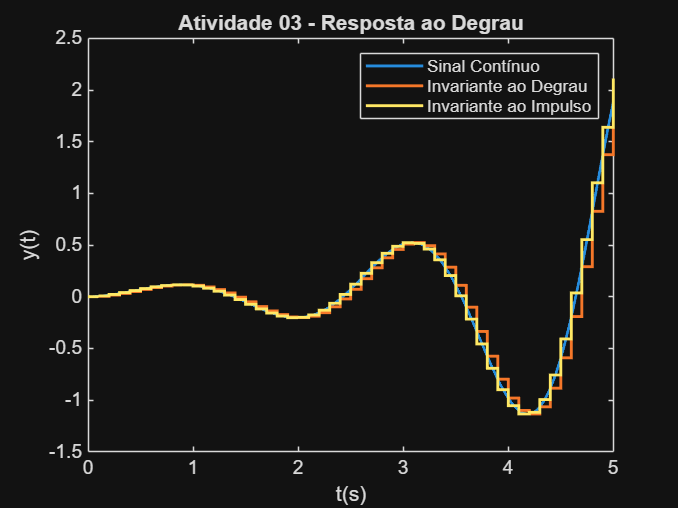

clear all
close all 
clc
% Definindo a função de transferência contínua % 
num = [1 3 2];
den = [1 7 8 56 105];
G = tf(num, den);
% Resposta ao impulso e ao degrau:
dt = 0.001;
t = 0:dt:5; %vetor tempo contínuo
[y_degrau, t] = step(G, t);
[y_impulso, t] = impulse(G, t);
Ts = 0.1;
% Obtendo as funções de transferência discretas:
Gd_zoh = c2d(G, Ts, 'zoh');
Gd_impulse = c2d(G, Ts, 'impulse');
td = 0:Ts:5; %vetor tempo discreto
[y_du1,td] = step(Gd_zoh, td);
[y_du2,td] = step(Gd_impulse, td);
[y_di1,td] = impulse(Gd_zoh, td);
[y_di2,td] = impulse(Gd_impulse, td);
figure
plot(t, y_degrau, 'LineWidth',1.5)
hold on
stairs(td, y_du1, 'LineWidth', 1.5)
stairs(td, y_du2, 'LineWidth', 1.5)
xlabel('t(s)')
ylabel('y(t)')
title('Atividade 03 - Resposta ao Degrau')
legend('Sinal Contínuo', 'Invariante ao Degrau', 'Invariante ao Impulso')

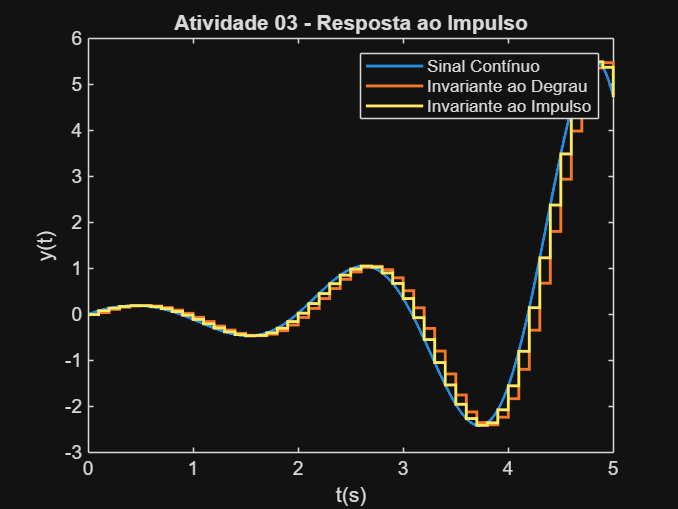

figure
plot(t, y_impulso, 'LineWidth',1.5)
hold on 
stairs(td, y_di1, 'LineWidth',1.5)
stairs(td, y_di2, 'LineWidth',1.5)
title('Atividade 03 - Resposta ao Impulso')
xlabel('t(s)')
ylabel('y(t)')
legend('Sinal Contínuo', 'Invariante ao Degrau', 'Invariante ao Impulso')

**Resposta:** Nota-se que, na resposta ao degrau, a discretização do mesmo (invariante ao degrau), "respeita" o sinal contínuo, enquanto o sinal discreto que é dado pela resposta ao impulso não. O mesmo ocorre para o outro sinal. onde a discretização invariante ao impulso "casa" com o sinal contínuo, enquanto o sinal discreto invariante ao degrau não. Isso mostra que os métodos de ZOH e Impulse representam bem o sinal contínuo. 

## Atividade 04 - Equação à Diferenças

Questão (1)

clear all 
close all 
clc 
% Definindo a função de transferência: 
syms s z T
num = [1 2];
den = [2 3 5];
G = tf(num,den);
num_sym = poly2sym(num, s);
den_sym = poly2sym(den, s);
G_sym = num_sym / den_sym;
pretty(G_sym)

     s + 2
--------------
   2
2 s  + 3 s + 5



% Obtendo Gd(z):
Ts = 0.1;
Gd_zoh = c2d(G, Ts, 'zoh');
Gd_zoh


Gd_zoh =
 
   0.05099 z - 0.04172
  ----------------------
  z^2 - 1.838 z + 0.8607
 
Sample time: 0.1 seconds
Discrete-time transfer function.


Com isso, encontra-se que a função Gd(z) é: 

Gd(z) = $\frac{0\ldotp 05099Z-0\ldotp 04172}{Z^2 -1\ldotp 838Z+0\ldotp 8607}$

Logo, com isso, obtêm-se que a equação à diferenças associada é dada por:

y[k] = 1.838y[k−1]−0.8607y[k−2]+0.05099u[k−1]−0.04172u[k−2]

Com isso, implementamos o seguinte código:

td = 0:Ts:5-Ts;
y = zeros(size(td));
u = ones(size(td));
for k=3:50
    y(k) = 1.838*y(k-1) - 0.8607*y(k-2) + 0.05099*u(k-1) - 0.04172*u(k-2)
end

y =          0         0    0.0093         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143         0         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101         0         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064         0         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064    0.4032         0         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064    0.4032    0.4007         0         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064    0.4032    0.4007    0.3986         0         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064    0.4032    0.4007    0.3986    0.3971         0         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064    0.4032    0.4007    0.3986    0.3971    0.3960         0         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064    0.4032    0.4007    0.3986    0.3971    0.3960    0.3954         0         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064    0.4032    0.4007    0.3986    0.3971    0.3960    0.3954    0.3951         0         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064    0.4032    0.4007    0.3986    0.3971    0.3960    0.3954    0.3951    0.3952         0         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064    0.4032    0.4007    0.3986    0.3971    0.3960    0.3954    0.3951    0.3952    0.3956         0


y =          0         0    0.0093    0.0263    0.0496    0.0779    0.1097    0.1438    0.1792    0.2149    0.2500    0.2838    0.3157    0.3453    0.3722    0.3961    0.4170    0.4348    0.4495    0.4613    0.4702    0.4764    0.4803    0.4819    0.4817    0.4798    0.4766    0.4723    0.4671    0.4613    0.4551    0.4488    0.4423    0.4361    0.4300    0.4243    0.4191    0.4143    0.4101    0.4064    0.4032    0.4007    0.3986    0.3971    0.3960    0.3954    0.3951    0.3952    0.3956    0.3962


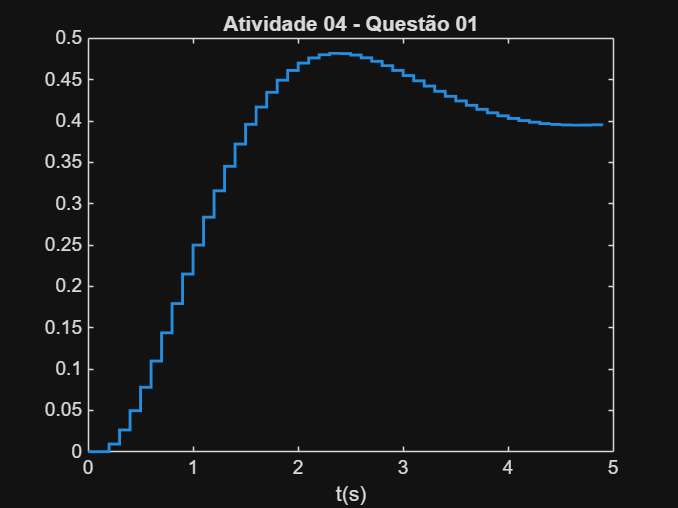

figure
stairs(td, y,'LineWidth',1.5)
title('Atividade 04 - Questão 01')
xlabel('t(s)')

Questão (2)

clear all 
close all 
clc
% Definindo a função de transferência: 
syms s z T
num = [1 0];
den = [1 0 1];
G = tf(num,den);
num_sym = poly2sym(num, s);
den_sym = poly2sym(den, s);
G_sym = num_sym / den_sym;
pretty(G_sym)

   s
------
 2
s  + 1



% Obtendo Gd(z):
Ts = 0.1;
Gd_zoh = c2d(G, Ts, 'zoh');
Gd_zoh


Gd_zoh =
 
  0.09983 z - 0.09983
  -------------------
   z^2 - 1.99 z + 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.


Com isso, encontra-se que a função Gd(z) é: 

Gd(z) = $\frac{0\ldotp 09983Z-0\ldotp 09983}{Z^2 -1\ldotp 99Z+1}$

Logo, com isso, obtêm-se que a equação à diferenças associada é dada por:

y[k] = 1.99y[k−1]−y[k−2]+0.09983u[k−1]−0.09983u[k−2]

Com isso, implementamos o seguinte código:

td = 0:Ts:5-Ts;
y = zeros(size(td));
u = ones(size(td));
for k=3:50
    y(k) = 1.99*y(k-1) - 1*y(k-2) + 0.09983*u(k-1) - 0.09983*u(k-2)
end

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


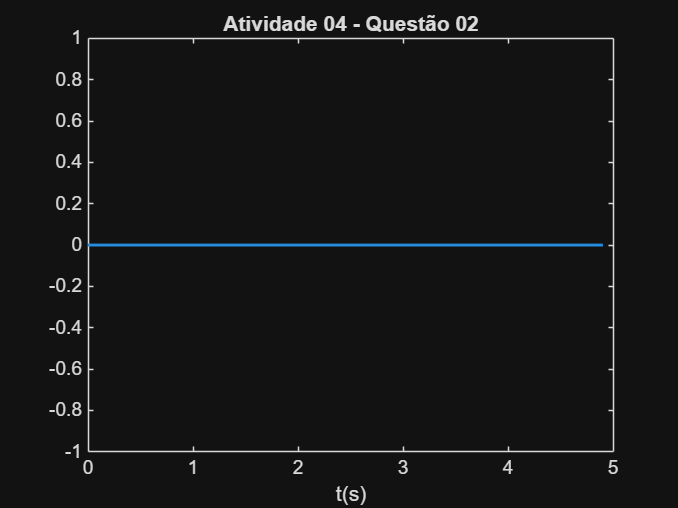

figure
stairs(td, y,'LineWidth',1.5)
title('Atividade 04 - Questão 02')
xlabel('t(s)')

## Atividade 05 - Circuito RC

Questão (1)

Primeiramente, aplica-se a transformada de Laplace nos elementos do circuito, obtendo-se:

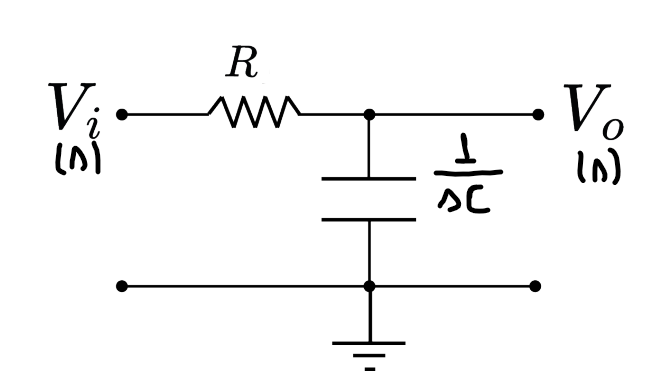

Aplicando o divisor de tensão, obtêm-se:


$$\textrm{Vout}\left(s\right)=\frac{\textrm{Vin}\left(s\right)\frac{1}{\textrm{sC}}}{R+\frac{1}{\textrm{sC}}}$$


Ajeitando a equação acima e isolando $\frac{\textrm{Vout}\left(s\right)}{\textrm{Vin}\left(s\right)}$, encontra-se: 


$$G\left(s\right)=\frac{\textrm{Vout}\left(s\right)}{\textrm{Vin}\left(s\right)}=\frac{1}{1+\textrm{sRC}}$$


Com a função G(s), é possível descrevê-la no código, como ilustrado abaixo:

clear all
close all
clc
%Definindo a função de transferência G(s):
R = 1;
C = 1;
num = 1;
mul = R*C;
G = tf(num, [mul 1]); 
syms s
num_sym = poly2sym(num, s)

$$num\_sym = 1$$

den_sym = poly2sym([mul 1], s);
G_sym = num_sym / den_sym

$$G\_sym = \frac{1}{s+1}$$

pretty(G_sym);

  1
-----
s + 1



Questão (2)

% Discretizando G(s) pelo método de Tustin
Ts = 0.01;
Gd_tustin = c2d(G, Ts, 'tustin');
Gd_tustin


Gd_tustin =
 
  0.004975 z + 0.004975
  ---------------------
        z - 0.99
 
Sample time: 0.01 seconds
Discrete-time transfer function.


Questão (3)

dt = 0.001;
t = 0:dt:5;
[y_degrau, t] = step(G, t)

y_degrau =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090
    0.0100
    0.0109
    0.0119
    0.0129
    0.0139


t =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090
    0.0100
    0.0110
    0.0120
    0.0130
    0.0140


td = 0:Ts:5;
[y_du,td] = step(Gd_tustin, td)

y_du =     0.0050
    0.0149
    0.0247
    0.0344
    0.0440
    0.0535
    0.0629
    0.0722
    0.0815
    0.0906
    0.0997
    0.1086
    0.1175
    0.1263
    0.1350


td =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900
    0.1000
    0.1100
    0.1200
    0.1300
    0.1400


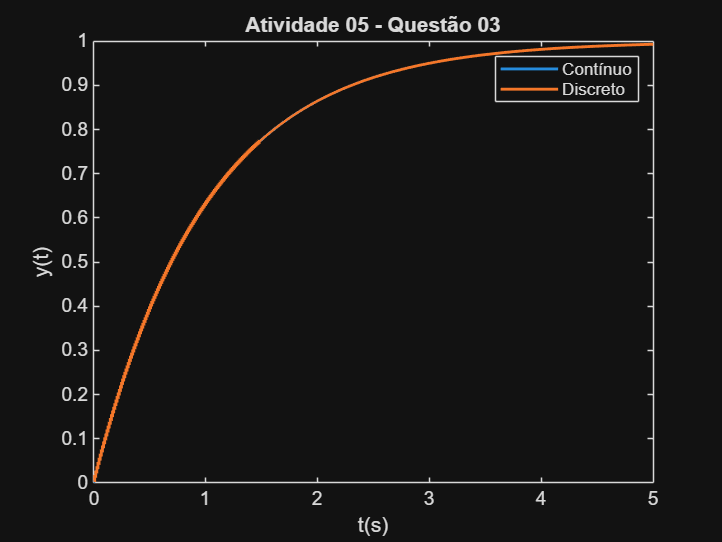

figure
plot(t, y_degrau, 'LineWidth', 1.5)
hold on
stairs(td, y_du, 'LineWidth', 1.5)
title('Atividade 05 - Questão 03')
xlabel('t(s)')
ylabel('y(t)')
legend('Contínuo','Discreto')

Questão (4)

dt = 0.001;
t = 0:dt:5;
[y_impulso, t] = impulse(G, t)

y_impulso =     1.0000
    0.9990
    0.9980
    0.9970
    0.9960
    0.9950
    0.9940
    0.9930
    0.9920
    0.9910
    0.9900
    0.9891
    0.9881
    0.9871
    0.9861


t =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090
    0.0100
    0.0110
    0.0120
    0.0130
    0.0140


td = 0:Ts:5;
[y_du2,td] = impulse(Gd_tustin, td)

y_du2 =     0.4975
    0.9901
    0.9802
    0.9705
    0.9608
    0.9513
    0.9418
    0.9324
    0.9231
    0.9140
    0.9049
    0.8959
    0.8869
    0.8781
    0.8694


td =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900
    0.1000
    0.1100
    0.1200
    0.1300
    0.1400


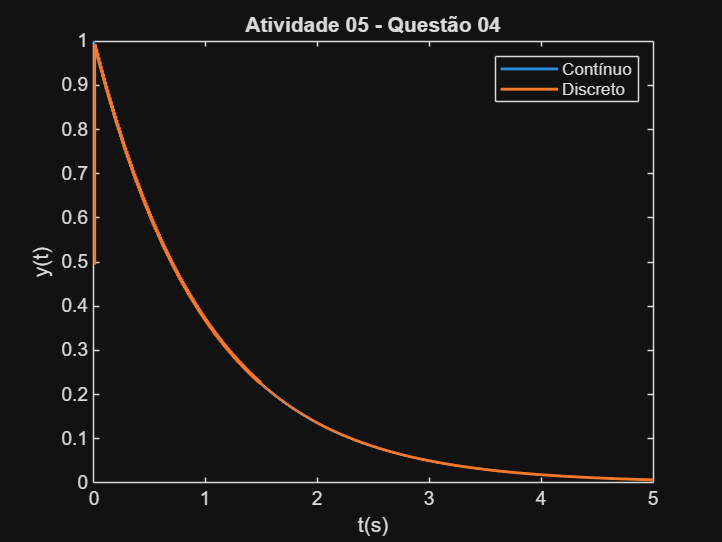

figure
plot(t, y_impulso, 'LineWidth', 1.5)
hold on
stairs(td, y_du2, 'LineWidth', 1.5)
title('Atividade 05 - Questão 04')
xlabel('t(s)')
ylabel('y(t)')
legend('Contínuo','Discreto')

Questão (5)

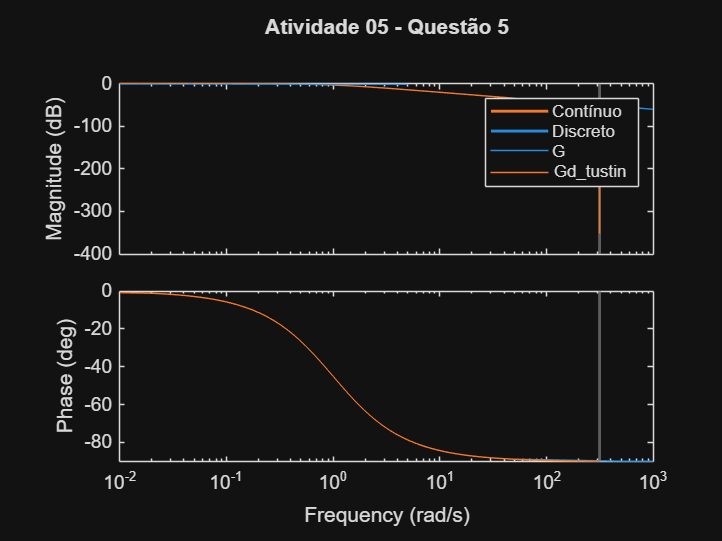

bode(G, Gd_tustin)
title('Atividade 05 - Questão 5')
legend('Contínuo','Discreto')

Questão (6)

Utilizando a equação presente em "Questão 2", tem-se a função Gd(z):


$$\textrm{Gd}\left(Z\right)=\frac{0\ldotp 004975Z+0\ldotp 004975}{Z-0\ldotp 99}$$


A partir desta, pode-se encontrar a equação à diferenças. No caso, obtêm-se: 

y[k] = 0.99*y[k−1]+0.004975*u[k]+0.004975*u[k−1]

td = 0:Ts:5-Ts;
y = zeros(size(td));
u = ones(size(td));
for k=2:50
    y(k) = 0.99*y(k-1) + 0.004975*u(k) + 0.004975*u(k-1)
end

y =          0    0.0100         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021         0         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090         0         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159         0         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226         0         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226    0.3294         0         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226    0.3294    0.3360         0         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226    0.3294    0.3360    0.3426         0         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226    0.3294    0.3360    0.3426    0.3491         0         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226    0.3294    0.3360    0.3426    0.3491    0.3556         0         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226    0.3294    0.3360    0.3426    0.3491    0.3556    0.3620         0         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226    0.3294    0.3360    0.3426    0.3491    0.3556    0.3620    0.3683         0         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226    0.3294    0.3360    0.3426    0.3491    0.3556    0.3620    0.3683    0.3746         0         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226    0.3294    0.3360    0.3426    0.3491    0.3556    0.3620    0.3683    0.3746    0.3808         0


y =          0    0.0100    0.0198    0.0296    0.0392    0.0488    0.0582    0.0676    0.0769    0.0861    0.0951    0.1041    0.1130    0.1219    0.1306    0.1392    0.1478    0.1563    0.1647    0.1730    0.1812    0.1893    0.1974    0.2054    0.2133    0.2211    0.2288    0.2365    0.2441    0.2516    0.2590    0.2664    0.2736    0.2809    0.2880    0.2951    0.3021    0.3090    0.3159    0.3226    0.3294    0.3360    0.3426    0.3491    0.3556    0.3620    0.3683    0.3746    0.3808    0.3869


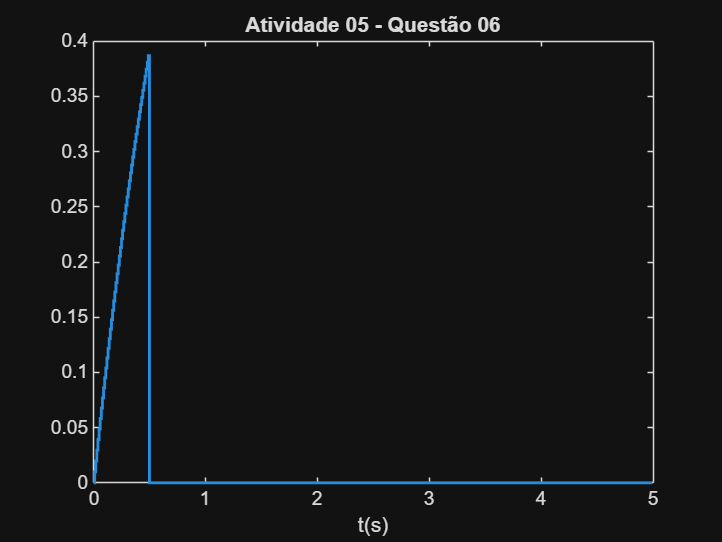

figure
stairs(td, y,'LineWidth',1.5)
title('Atividade 05 - Questão 06')
xlabel('t(s)')

Questão (7)

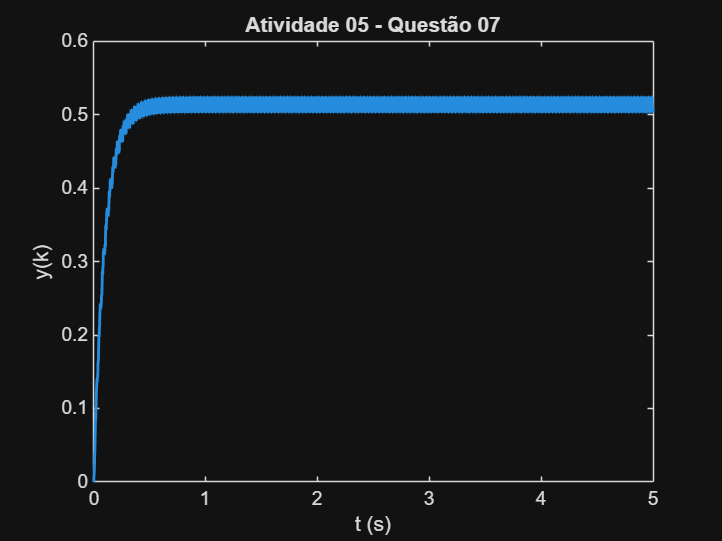

%help prbs
Ts = 0.001; % período de amostragem
td = 0:Ts:5; % vetor de tempo
N = numel(td); % número de amostras
u = prbs(5,N);
y = zeros(size(td));
for k = 2:N
    y(k) = 0.99*y(k-1) + 0.004975*u(k) + 0.004975*u(k-1);
end
figure;
stairs(td, y, 'LineWidth', 1.5)
title('Atividade 05 - Questão 07')
xlabel('t (s)')
ylabel('y(k)')

## Atividade 06 - Identificação de Sistema

Primeiramente, carrega-se as variáveis no sistema. Note que para a utilização da tfest é necessário uma estimação do número de polos e zeros do sistema. 

load('/MATLAB Drive/identData.mat')
%whos
Ts = 0.001;
tau = 0;
sigma=0.1;
polos = 2;
zeros = 1;
data = iddata(y, u, Ts)

data = Time domain data set with 101 samples.
Sample time: 0.001 seconds            
                                      
Outputs      Unit (if specified)      
   y1                                 
                                      
Inputs       Unit (if specified)      
   u1                                 
                                      
Data Properties

%disp(data)
%plot(data)
%help tfest

**Código para identificação do sistema**

***obs: **este trecho do código foi retirado do código exemplo disponibilizado no e-disciplinas

N=floor(numel(y)*0.7);
ident_data=iddata(y(1:N)+sigma*randn(size(y(1:N))),u(1:N),Ts);
test_data=iddata(y(N+1:end)+sigma*randn(size(y(N+1:end))),u(N+1:end),Ts);

**Algoritimo de identificação do sistema:**

***obs:** o resultado obtido varia de acordo com o valor estabelecido para polos e zeros, na primeira seção desta atividade. Trecho do código modificado à partir do exemplo disponibilizado no e-disciplinas

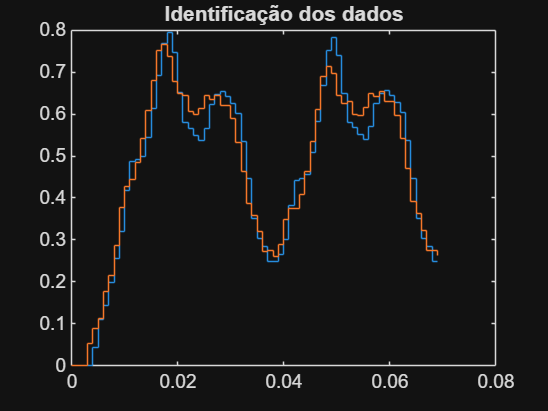

sys_ident=tfest(data,polos,zeros,0,'Ts',Ts); 
[num,den]=tfdata(sys_ident);
G_ident=tf(num,den,Ts);
z=tf('z');
G_ident=z^(-tau/Ts)*G_ident;

**Algoritimo para comparação dos resultados**

***obs: **este trecho do código foi retirado do código exemplo disponibilizado no e-disciplinas

figure
stairs(td(1:N),y(1:N))
yident=lsim(G_ident,u(1:N),td(1:N),y(1));
hold on
stairs(td(1:N),yident)
title('Comparação dos resultados')

Por fim, este código apresenta os gráficos de resposta ao degrau, impulso e frequência do sistema que foi identificado pelo algorítimo acima.

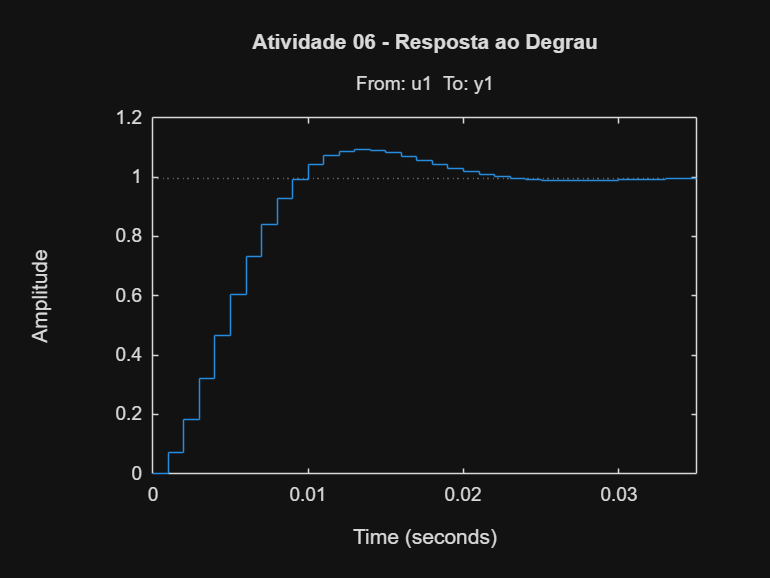

figure;
step(sys_ident)
title('Atividade 06 - Resposta ao Degrau');

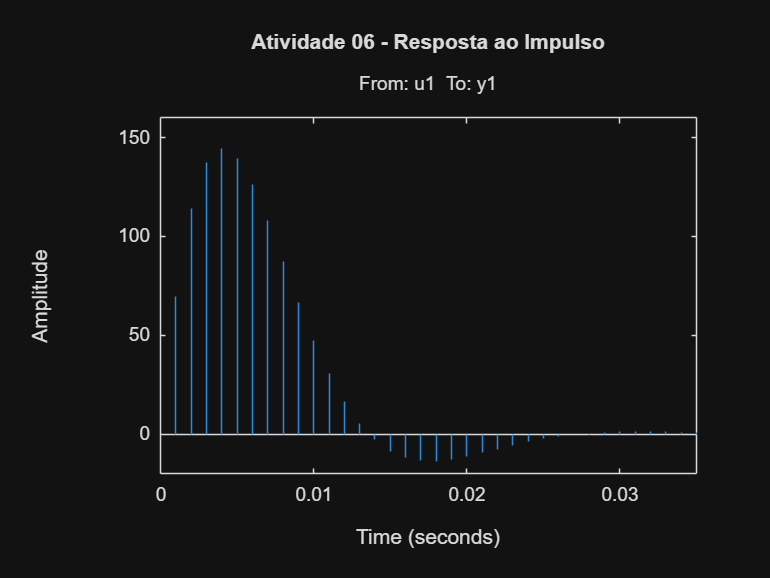

figure;
impulse(sys_ident)
title('Atividade 06 - Resposta ao Impulso');

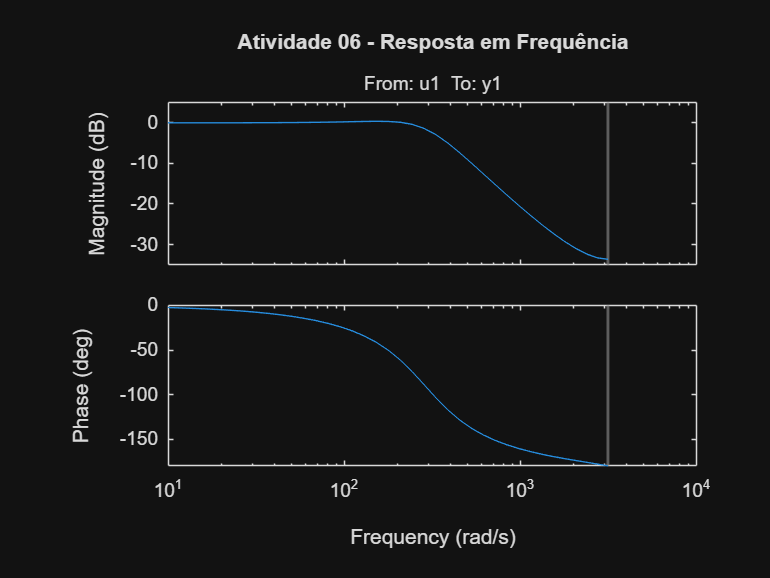

figure;
bode(sys_ident)
title('Atividade 06 - Resposta em Frequência')